### Load neural data

m = F;
MName = F.AnimalID;
m_neural = m.MS{1}.FiltTraces(901:end,logical(m.MS{1}.goodCellVec)); % remove first 2 min
m_tstamp = m.TimeStamp.Ts{1}.Ms(901:end);
m_neural_bined = BinData(m_neural, 5, 'mean'); % bin to 1/3 s
m_tstamp_bined = BinData(m_tstamp, 5, 'mean');

### Load tracking data

tracks_matrix_raw = h5read('PairQD6_XZ91.h5','/tracks');
disp(size(tracks_matrix_raw))

       20880           5           2



% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix_raw = fillmissing(tracks_matrix_raw, 'movmean', 7, 1);

### Read timestamp and bin data, trucate tracking to match length, align timestamp

% match bv timestamp and bv video (tracking)
tstamp_raw = csvread('PairQD6_XZ91.csv', 1);
tstamp_raw = tstamp_raw(size(tstamp_raw,1)-size(tracks_matrix_raw,1)+1:end,2); % match video
% match neural data timestamp 
% neural is almost always shorter (remove first 1-2 minutes) whereas bv
% only ~200-600 frames
neural_starts_here = find(tstamp_raw>=m_tstamp(1),1)

neural_starts_here =         1362


tracks_matrix = tracks_matrix_raw(neural_starts_here:end,:,:,:);
tstamp = tstamp_raw(neural_starts_here:end);

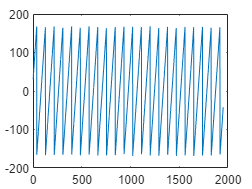


% bin Data
tracks_bined = BinData(tracks_matrix, 10, 'mean');
time_bined = BinData(tstamp, 10, 'mean');
% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));
% timestamp map
[idx1,idx2,tdifference] = TStampAlign(time_bined,m_tstamp_bined);
figure, plot(tdifference);

m_tstamp_bined = m_tstamp_bined(idx2,:);
m_neural_bined = m_neural_bined(idx2,:);

### Quadrant position states

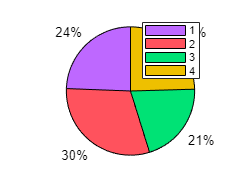

qcenter = [292,249]; %[ycenter, xcenter]
qcode = [head_coord(:,:,1)<=qcenter(1), head_coord(:,:,2) > qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;
[b,bg,bp] = groupcounts(qseries);
% time spent in each quadrant
colors = maxdistcolor(length(bp), @sRGB_to_CIELab,'Lmin',0.6,'Lmax',0.8,'Cmin',0.5,'Cmax',0.7);
figure, pie(bp/100);legend(num2str(bg)); colormap(colors);

### Get PCs and overlay plot with quadrant state

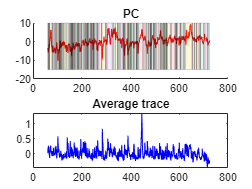

coef = pca(zscore(m_neural_bined));
PCs = m_neural_bined * coef;
[onset, offset] = FindConsecutiveOnsetOffset(qseries);
figure, ax = subplot(2,1,1,'NextPlot','add'); plot(ax,m_tstamp_bined/1000,PCs(:,1),'r');

% patch each quadrant
for qn = 1:length(onset)
    onset_t = onset{qn}; offset_t = offset{qn};ccolor = colors(qn,:);
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end
title('PC');
% plot average plot
subplot(2,1,2);plot(m_tstamp_bined/1000, mean(m_neural_bined,2),'b-');
title('Average trace');

### Prepare training/test set

o_idx = find(qseries==1); % quadrant 1
t_idx = find(qseries==2); % 2
th_idx = find(qseries==3); % 3
f_idx = find(qseries==4); % 4
idxs = {o_idx, t_idx, th_idx, f_idx};
Y = qseries;
% prepare training/test set
m_neural_bined = zscore(m_neural_bined);

### One vs all

f = figure;
for kd = 1:4    
    kfold = 10; cvspace = 45;
    X_temp = m_neural_bined;
    Y_temp = Y; 
    Y_temp(idxs{kd}) = 1;Y_temp(setdiff(1:length(Y_temp), idxs{kd})) = 0;
%     part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    for i = 1:10
        [perform_, perform_shifted_] = OnevOneDecoder(X_temp, Y_temp, kfold, cvspace,'logistic','accuracy');
        perform = [perform;perform_];
        perform_shifted = [perform_shifted;perform_shifted_];
    end
    a = subplot(2,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(idxs{kd})/length(Y_temp), 1-length(idxs{kd})/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(kd),'-vs-all']); ylabel('Accuracy'); ylim('padded');
end

### One vs one

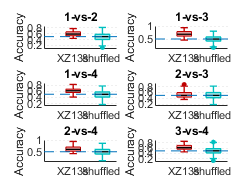

f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    % downsample to balance class
    [mlen,midx] = min([length(idxs{combines(kd,1)}),length(idxs{combines(kd,2)})]);
%     m_neural_bined_ovo = m_neural_bined(cat(1,idxs{combines(kd,:)}),:);
%     m_neural_bined_ovo = neural_proj(cat(1,idxs{combines(kd,:)}),1:3);
    dsample_idx = datasample(idxs{setdiff(combines(kd,:),combines(kd,midx))}, mlen,'Replace',false);
    m_neural_bined_ovo = m_neural_bined(cat(1,idxs{combines(kd,midx)},dsample_idx),:);
    Y_temp = Y(cat(1,idxs{combines(kd,midx)},dsample_idx));
    % same vs neighbor
    kfold = 10; cvspace=45;
%     Y_temp = Y(cat(1,idxs{combines(kd,:)}));
    perform = [];
    perform_shifted = [];
    for i = 1:10
        try
            [perform_, perform_shifted_] = OnevOneDecoder(m_neural_bined_ovo, Y_temp, kfold, cvspace,'lda','accuracy');
            perform = [perform;perform_];
            perform_shifted = [perform_shifted; perform_shifted_];
        end
    end
    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
%     random_guess_ = max(length(idxs{combines(kd,1)})/length(Y_temp), 1-length(idxs{combines(kd,1)})/length(Y_temp));
    random_guess_ = 0.5;
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end

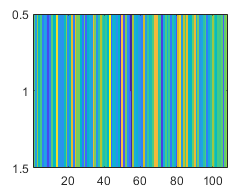

% PSTH
figure, imagesc(median(m_neural_bined(o_idx,:),1));

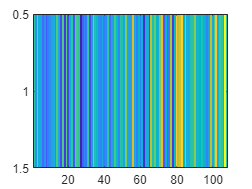

[~,oidx] = sort(median(m_neural_bined(o_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(t_idx,:),1));

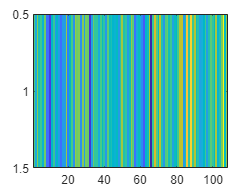

[~,tidx] = sort(median(m_neural_bined(t_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(th_idx,:),1));

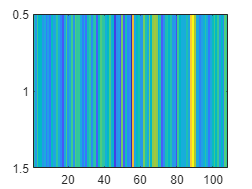

[~,thidx] = sort(median(m_neural_bined(th_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(f_idx,:),1));

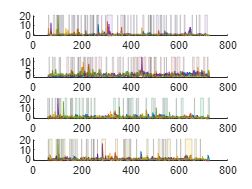

[~,fidx] = sort(median(m_neural_bined(f_idx,:),1),'descend');
qidx = {oidx,tidx,thidx,fidx};
f = figure; 
for qn = 1:length(onset)
    onset_t = onset{qn}; offset_t = offset{qn};ccolor = colors(qn,:);
    ax = subplot(4,1,qn,'Parent',f,'NextPlot','add');
    idx = qidx{qn};
    plot(ax,1/1000*time_bined,m_neural_bined(:, idx(1:5)));
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end

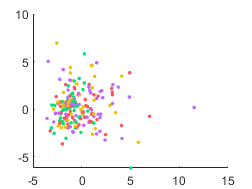

bout_mean_matrix = []; % each bout take mean
bout_label = [];
for i = 1:length(onset)
    onset_t = onset{i};
    offset_t = offset{i};
    for j = 1:length(onset_t)
        this_bout_mean = mean(m_neural_bined(onset_t(j):offset_t(j),:),1); % 1xn neuron
        bout_mean_matrix = [bout_mean_matrix; this_bout_mean];
        bout_label = [bout_label; i];
    end
end

ncoeff = pca(bout_mean_matrix);
bout_proj = bout_mean_matrix * ncoeff;
f= figure; ax = axes('Parent',f,'NextPlot','add');
for i = 1:length(onset)
    plot3(ax,bout_proj(bout_label==i,1),bout_proj(bout_label==i,2),bout_proj(bout_label==i,3),'o','Color',colors(i,:),'MarkerFaceColor',colors(i,:),'MarkerSize',2);
end

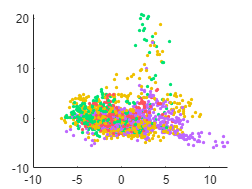

[ncoeff,~,~,~,explained] = pca(m_neural_bined);
neural_proj = m_neural_bined * ncoeff;
f = figure; ax = axes('Parent', f, 'NextPlot', 'add');
for i = 1:length(onset)
    plot3(ax,neural_proj(idxs{i},1),neural_proj(idxs{i},2),neural_proj(idxs{i},3),'o','Color',colors(i,:),'MarkerFaceColor',colors(i,:),'MarkerSize',2);
end

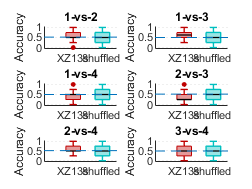

% classifier performance on bouts basis
f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    bout_neural_subset = bout_mean_matrix([find(bout_label == combines(kd,1));find(bout_label == combines(kd,2))],:);
    Y_temp = bout_label([find(bout_label == combines(kd,1));find(bout_label == combines(kd,2))]);
    fold = 5;
    part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    for i = 1:5
        try
            [perform_, perform_shifted_] = OnevOneDecoder(bout_neural_subset, Y_temp, kfold, 0,'lda','accuracy');
            perform = [perform;perform_];
            perform_shifted = [perform_shifted; perform_shifted_];
        end

    end
    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(find(Y_temp==combines(kd,1)))/length(Y_temp), 1-length(find(Y_temp==combines(kd,1)))/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end

% run ROC analysis per cell
pos_cell = cell(1,4);
for j = 1:length(idxs)
    for i = 1:size(m_neural_bined,2)
        posidx = idxs{j};
        Y_temp = zeros(size(m_neural_bined,1),1);
        Y_temp(posidx) = 1;
        [~,~,~,AUC] = perfcurve(Y_temp, m_neural_bined(:,i),1);
        rand_AUC = [];
        for k = 1:500 % cirshift
            Y_temp = circshift(Y_temp, randi(length(Y_temp)),1);
            [~,~,~,tempAUC] = perfcurve(Y_temp, m_neural_bined(:,i),1);
            rand_AUC = [rand_AUC; tempAUC];
        end
        if AUC >= prctile(rand_AUC, 97.5)
            pos_cell{j} = [pos_cell{j}; i];
            fprintf('Cell %d, quadrant %d positive\n', i, j);
        end
    end
end

Cell 5, quadrant 1 positive
Cell 13, quadrant 1 positive
Cell 16, quadrant 1 positive
Cell 24, quadrant 1 positive
Cell 34, quadrant 1 positive
Cell 36, quadrant 1 positive
Cell 41, quadrant 1 positive
Cell 44, quadrant 1 positive
Cell 45, quadrant 1 positive
Cell 50, quadrant 1 positive
Cell 57, quadrant 1 positive
Cell 61, quadrant 1 positive
Cell 86, quadrant 1 positive
Cell 91, quadrant 1 positive
Cell 116, quadrant 1 positive
Cell 123, quadrant 1 positive
Cell 131, quadrant 1 positive
Cell 134, quadrant 1 positive
Cell 170, quadrant 1 positive
Cell 179, quadrant 1 positive
Cell 180, quadrant 1 positive
Cell 194, quadrant 1 positive
Cell 201, quadrant 1 positive
Cell 208, quadrant 1 positive
Cell 211, quadrant 1 positive
Cell 222, quadrant 1 positive
Cell 224, quadrant 1 positive
Cell 225, quadrant 1 positive
Cell 232, quadrant 1 positive
Cell 233, quadrant 1 positive
Cell 254, quadrant 1 positive
Cell 256, quadrant 1 positive
Cell 266, quadrant 1 positive
Cell 2, quadrant 2 positi

% plot positive cells
for j = 1:length(pos_cell)
    figure, ax = axes('Parent',gcf,'NextPlot','add');
    plot(ax,time_bined/1000, m_neural_bined(:,pos_cell{j})+ones(size(m_neural_bined,1),1)*(0:length(pos_cell{j})-1)*10);
    onset_t = onset{j};
    offset_t = offset{j};
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end

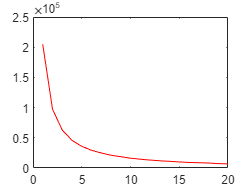

% cluster neurons by their activity
mean_dist_to_c1 = [];
for kn = 1:20
    [idx, centro, sumd] = kmeans(transpose(m_neural_bined), kn);
    mean_dist_to_c1 = [mean_dist_to_c1, mean(sumd)];
end

figure,plot(1:20, mean_dist_to_c1,'r');

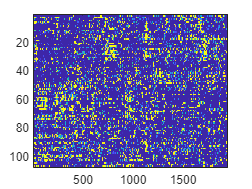

kn=10; % specify number of clusters
rng(42); % set random seed
idx1 = kmeans(m_neural_bined', kn);
[~,c_order1] = sort(idx1);
figure, imagesc(transpose(m_neural_bined(:,c_order1)), [0,1]);

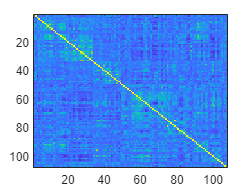

figure, imagesc(corr(m_neural_bined(:,c_order1)));

### Plot activity map

% divide into 20x50 grid
% load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
avg_grid_stack = [];
arena = imread('XZ91_arena.tif');
xgrid = linspace(1,size(arena,1),28);
ygrid = linspace(1,size(arena,2),32);
nrow= 5; ncol=5;
red = cat(3, ones(size(arena,[1,2])), zeros(size(arena,[1,2])), zeros(size(arena,[1,2])));
blue = cat(3, zeros(size(arena,[1,2])), zeros(size(arena,[1,2])), ones(size(arena,[1,2])));
yellow = cat(3, ones(size(arena,[1,2])), ones(size(arena,[1,2])), zeros(size(arena,[1,2])));
cyan = cat(3, zeros(size(arena,[1,2])), ones(size(arena,[1,2])), ones(size(arena,[1,2])));
[~,idx1xx] = sort(idx1);
f = figure('Position',[767,203,1613,1132]);
PC1_max = 0;
for j = 1:25 %numel(idx1xx)
    grid_count = zeros(32,28);
    grid_neuron = zeros(32,28);
%     avg_trace = m_neural_bined(:,j);%avg_grid_idx(j));% transit_cells(j)); %idx1xx(j));
    avg_trace = PCs(:,j); avg_trace = (avg_trace-mean(avg_trace)).^2;
    for i = 1:size(head_coord,1)
        current_x = head_coord(i,1,2);
        current_y = head_coord(i,1,1);
        xidx = find(xgrid>=current_x,1);
        yidx = find(ygrid>=current_y,1);
        grid_neuron(yidx,xidx) = grid_neuron(yidx,xidx) + avg_trace(i);
        grid_count(yidx,xidx) = grid_count(yidx,xidx) + 1;
      
    end
    ax = subplot(nrow,ncol,j,'Parent',f,'NextPlot','add');
%     title(num2str(j));
    imshow(arena,'Parent',ax);
    avg_grid = grid_neuron./grid_count;
    avg_grid(isnan(avg_grid)) = 0;
    avg_grid = permute(avg_grid,[2,1]);
    
    if j == 1
        PC1_max = quantile(avg_grid,0.98,'all');
    end
    avg_grid = uint8(255*mat2gray(avg_grid,[0,PC1_max]));
%     avg_grid = uint8(255*mat2gray(avg_grid,[0,quantile(avg_grid,1,'all')]));
    r = imshow(red,'Parent', ax);
    set(r,'AlphaData', imresize(avg_grid, size(arena,[1,2])));
%     imagesc(ax, imresize(avg_grid,size(arena,[1,2])),'AlphaDataMapping','scaled');
%     colormap(ax,red_colormap);clim([0,Inf]);
end
ha = get(gcf,'children');
for j = 1:length(ha)
    axpos = [mod(ncol*nrow-j,ncol)/ncol, 1-1/nrow-floor((nrow*ncol-j)/ncol)/nrow, 1/ncol, 1/nrow];
    set(ha(j),'position',axpos);
end

### Trajectory heat map

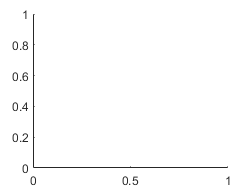

f = figure; ax = axes('Parent',f,'NextPlot','add');

grid_count = permute(grid_count,[2,1]);
grid_count = uint8(255*mat2gray(grid_count,[0,max(grid_count,[],'all')]));

Error using mat2gray
Expected input number 2, LIMITS, to be one of these types:

double

Instead its type was uint8.

Error in mat2gray (line 41)
  validateattributes(limits,{'double'},{'numel',2},mfilename,'LIMITS',2);

imshow(arena,'Parent',ax);
b = imshow(blue,'Parent',ax);
set(b,'AlphaData',imresize(grid_count, size(arena,[1,2])));

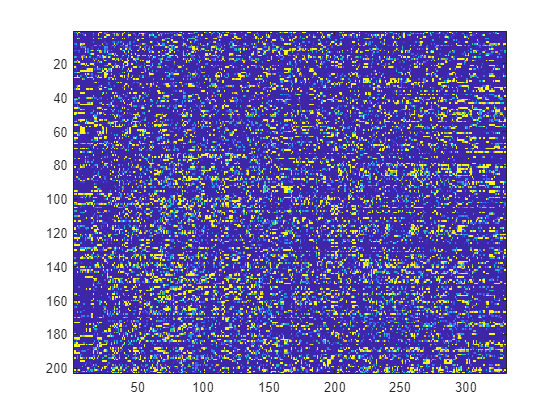

% Classify activity map
% load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
avg_grid_stack = [];
xgrid = linspace(1,size(arena,1),28);
ygrid = linspace(1,size(arena,2),32);
for j = 1:size(m_neural_bined,2)
    grid_count = zeros(32,28);
    grid_neuron = zeros(32,28);
    avg_trace = m_neural_bined(:,j);% transit_cells(j)); %idx1xx(j));
    for i = 1:size(head_coord,1)
        current_x = head_coord(i,1,2);
        current_y = head_coord(i,1,1);
        xidx = find(xgrid>=current_x,1);
        yidx = find(ygrid>=current_y,1);
        grid_neuron(yidx,xidx) = grid_neuron(yidx,xidx) + avg_trace(i);
        grid_count(yidx,xidx) = grid_count(yidx,xidx) + 1;
      
    end
    avg_grid = grid_neuron./grid_count;
    avg_grid(isnan(avg_grid)) = 0;
    avg_grid = permute(avg_grid,[2,1]);
    avg_grid_stack = cat(1,avg_grid_stack,reshape(avg_grid,1,[]));
end

% remove 0 columns
avg_grid_stack(:,find(sum(avg_grid_stack,1)==0)) = [];
avg_grid_stack = zscore(avg_grid_stack,[],2);
figure, imagesc(avg_grid_stack, [0,1]);

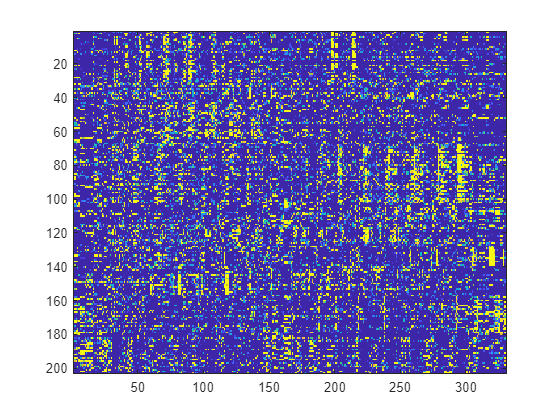


% k means
kn=10; % specify number of clusters
rng(42); % set random seed
idx_grid = kmeans(avg_grid_stack, kn);
[~,avg_grid_idx] = sort(idx_grid);
figure, imagesc(avg_grid_stack(avg_grid_idx,:), [0,1]);

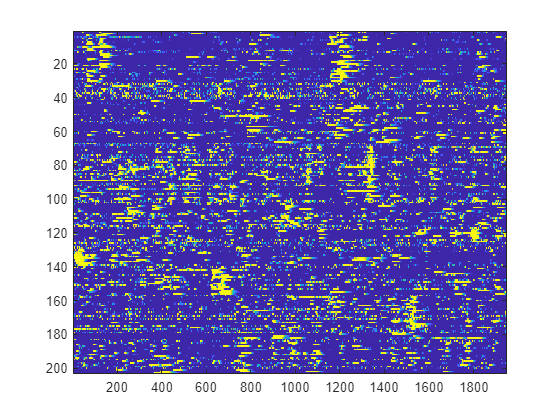

figure, imagesc(transpose(m_neural_bined(:,avg_grid_idx)),[0,1]);

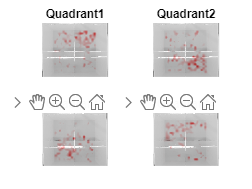

% Activity map of ROC cells
% load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
arena = imread('XZ135_arena.tif');
xgrid = linspace(1,size(arena,1),28);
ygrid = linspace(1,size(arena,2),32);
 

% avg_trace = mean(zscore(m_neural_bined(:,find(idx1==1))),2); % plot cluster

% avg_trace = PCs(:,1); % plot PC
f = figure;
for j = 1:4
    avg_trace = mean(zscore(m_neural_bined(:,pos_cell{j})),2); % plot ROC
    grid_count = zeros(32,28);
    grid_neuron = zeros(32,28);
    for i = 1:size(head_coord,1)
        current_x = head_coord(i,1,2);
        current_y = head_coord(i,1,1);
        xidx = find(xgrid>=current_x,1);
        yidx = find(ygrid>=current_y,1);
        grid_neuron(yidx,xidx) = grid_neuron(yidx,xidx) + avg_trace(i);
        grid_count(yidx,xidx) = grid_count(yidx,xidx) + 1;
    end
%     f= figure; ax = axes('Parent',f,'NextPlot','add');
    ax = subplot(2,2,j,'Parent',f,'NextPlot','add');
    imshow(arena,'Parent',ax);
    avg_grid = grid_neuron./grid_count;
    avg_grid(isnan(avg_grid)) = 0;
    avg_grid = permute(avg_grid,[2,1]);
    imagesc(ax, imresize(avg_grid,size(arena,[1,2])),'AlphaDataMapping','scaled');
    colormap(ax,red_colormap);clim([0,Inf]);
    title(['Quadrant',num2str(j)])
end

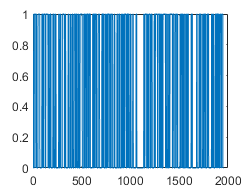

% find the transition moments
transit_moments = zeros(length(qseries),1); transit_moments(find(diff(qseries)~=0)) = 1;
temp = find(transit_moments==1);
for i = 1:length(temp)
%     disp(i)
    transit_moments(max(1,temp(i)-2):min((temp(i)+3),length(transit_moments))) = 1;
end
figure, plot(transit_moments)

% find transit responsive cells
transit_cells = [];
for i = 1:size(m_neural_bined,2)
    [~,~,~,AUC] = perfcurve(transit_moments, m_neural_bined(:,i),1);
    rand_AUC = [];
    for k = 1:500 % cirshift
        transit_temp = circshift(transit_moments, randi(length(transit_moments)),1);
        [~,~,~,tempAUC] = perfcurve(transit_temp, m_neural_bined(:,i),1);
        rand_AUC = [rand_AUC; tempAUC];
     end
     if AUC >= prctile(rand_AUC, 97.5)
        transit_cells = [transit_cells, i];
        fprintf('Cell %d, transit positive\n', i);
     end
end

Cell 5, transit positive
Cell 43, transit positive
Cell 7, transit positive
Cell 43, transit positive
Cell 8, transit positive
Cell 43, transit positive
Cell 12, transit positive
Cell 43, transit positive
Cell 13, transit positive
Cell 43, transit positive
Cell 15, transit positive
Cell 43, transit positive
Cell 23, transit positive
Cell 43, transit positive
Cell 26, transit positive
Cell 43, transit positive
Cell 29, transit positive
Cell 43, transit positive
Cell 32, transit positive
Cell 43, transit positive
Cell 36, transit positive
Cell 43, transit positive
Cell 47, transit positive
Cell 43, transit positive
Cell 51, transit positive
Cell 43, transit positive
Cell 57, transit positive
Cell 43, transit positive
Cell 58, transit positive
Cell 43, transit positive
Cell 59, transit positive
Cell 43, transit positive
Cell 69, transit positive
Cell 43, transit positive
Cell 70, transit positive
Cell 43, transit positive
Cell 71, transit positive
Cell 43, transit positive
Cell 72, transi

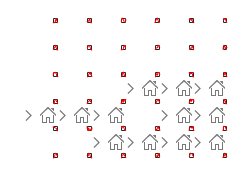

% plot PSTH, relationship with speed, bootstrap comparison
transit_window = transit_moments;
transit_moments = [find(diff(qseries)~=0);length(qseries)];
% only keep the isolated moments (within +-2s no other transit)
transit_to_plot= find(diff(transit_moments)>6);
transit_to_plot = intersect(transit_to_plot, transit_to_plot+1);
f = figure;
for i = 1:length(transit_cells)
    ax = subplot(nrow,ncol,i,'Parent',f,'NextPlot','add');
    PSTH(m_neural_bined(:,transit_cells(i)),transit_moments(transit_to_plot),6,ax);
    title(num2str(i))
end

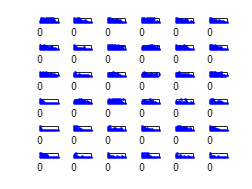

% relationship with speed 2s window
speed = squeeze(head_coord(3:end,:,:) - head_coord(1:end-2,:,:));
speed = sqrt(sum(speed.^2,2));
figure;
for i = 1:numel(transit_cells)
    subplot(nrow,ncol,i);
    plot(speed,(m_neural_bined(1:end-2,transit_cells(i))+m_neural_bined(2:end-1,transit_cells(i)))/2,'b.');
    mdl_temp = fitlm(speed, (m_neural_bined(1:end-2,transit_cells(i))+m_neural_bined(2:end-1,transit_cells(i)))/2);
    title(num2str(mdl_temp.Rsquared.Ordinary));
end

% apply time threshold, remove first t second and last t second
tthreshold = 6;
duration = cell(1,4);
bout_idx = cell(1,4);
idxs_2 = cell(1,4);
for i = 1:4
    duration{i} = offset{i}-onset{i}+1;
    bout_idx{i} = find(duration{i}> 2*tthreshold);
    for j = 1:length(bout_idx{i})
        idxs_2{i} = [idxs_2{i},(onset{i}(bout_idx{i}(j))+tthreshold):(offset{i}(bout_idx{i}(j))-tthreshold)];
    end
end

### Behavior characterize

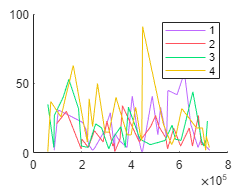

% dwelling duration over time
f = figure; ax = axes('Parent',f,'NextPlot','add');
for i = 1:4 
    onset_idx = onset{i};
    onset_t = time_bined(onset_idx);
    plot(ax,onset_t, duration{i},'Color',colors(i,:));
end
legend({'1','2','3','4'})

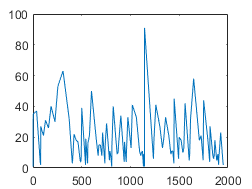

% pool all
[~, tmpidx] = sort(cat(2,onset{:}));
temp_1 = cat(2,onset{:}); temp_2 = cat(2,duration{:});
figure, plot(temp_1(tmpidx), temp_2(tmpidx))

f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    X_temp = m_neural_bined(cat(2,idxs_2{combines(kd,:)}),:);
    
    % same vs neighbor
    kfold = 10; cvspace=45;
    Y_temp = Y(cat(2,idxs_2{combines(kd,:)}));
    perform = []; perform_shifted = [];
    for i = 1:10
        try
            [perform_, perform_shifted_] = OnevOneDecoder(X_temp, Y_temp, kfold, cvspace,'lda');
            perform = [perform;perform_];
            perform_shifted = [perform_shifted;perform_shifted_];
        end
    end
    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(idxs_2{combines(kd,1)})/length(Y_temp), 1-length(idxs_2{combines(kd,1)})/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end

Quadrant transition